# Interactive MATLAB Lab 1.8: Solution-Type Explorer

In a Live Script, turn "mode" into a drop-down control. Use y0, K, or c as the active parameter for the selected mode.

Clairaut equation: y = x y' + (y')^2


Selected family member:


$$x+1$$

Singular solution:


$$-\frac{x^{2}}{4}$$

Verification:


   1



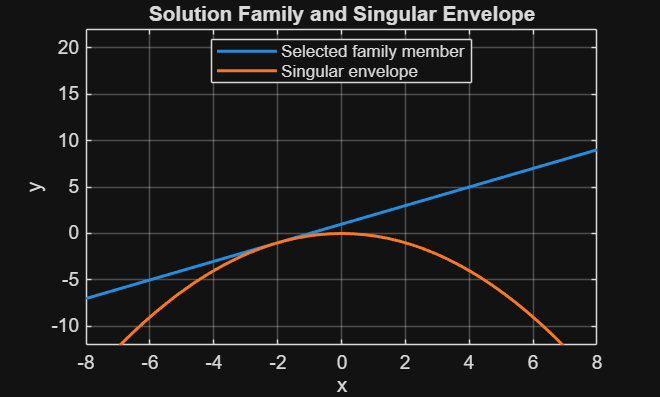

mode = "Singular Solution";   % Options: "General and Particular", "Equilibrium Solutions", "Singular Solution"
y0 = 2;
K = 8;
c = 1;

switch mode
    case "General and Particular"
        syms x y(x)

        ode = diff(y,x) == 2*x*y;
        generalSolution = dsolve(ode);
        particularSolution = dsolve(ode,y(0) == y0);

        disp("Differential equation: y' = 2xy")
        disp("General solution:")
        disp(generalSolution)
        disp("Initial condition: y(0) = " + string(y0))
        disp("Particular solution:")
        disp(particularSolution)

        figure
        fplot(particularSolution,[-1.5 1.5],'LineWidth',1.5)
        grid on
        xlabel('x')
        ylabel('y')
        title('Particular Solution Selected by the Initial Condition')

    case "Equilibrium Solutions"
        syms q
        equilibria = solve(q*(1-q/K) == 0,q);

        disp("Autonomous equation: q' = q(1-q/K)")
        disp("Carrying capacity K: " + string(K))
        disp("Equilibrium solutions:")
        disp(equilibria)

        figure
        fplot(@(t) 0*t,[0 10],'LineWidth',1.5)
        hold on
        fplot(@(t) K+0*t,[0 10],'LineWidth',1.5)
        hold off
        grid on
        xlabel('t')
        ylabel('q')
        title('Constant Equilibrium Solutions')
        legend('q=0','q=K','Location','best')

    case "Singular Solution"
        syms x

        family = c*x + c^2;
        singularSolution = -x^2/4;
        verificationResidual = simplify( ...
            singularSolution - ...
            (x*diff(singularSolution,x) + diff(singularSolution,x)^2) );

        verified = isequal(verificationResidual,sym(0));

        disp("Clairaut equation: y = x y' + (y')^2")
        disp("Selected family member:")
        disp(family)
        disp("Singular solution:")
        disp(singularSolution)
        disp("Verification:")
        disp(verified)

        figure
        fplot(family,[-8 8],'LineWidth',1.5)
        hold on
        fplot(singularSolution,[-8 8],'LineWidth',1.5)
        hold off
        ylim([-12 22])
        grid on
        xlabel('x')
        ylabel('y')
        title('Solution Family and Singular Envelope')
        legend('Selected family member','Singular envelope','Location','best')
end